# Week 2

Katie Foster

data = readtable('Parkinsons.txt');

## Part 1

#### 2. `If you randomly select someone from your study group who tested positive according to your screening test (screen ==1), what is the probability that they actually have Parkinson’s disease?`

`P( actual=1 | screen=1 ) = P(A`∩`B)/P(B)`

AnB = sum((data.actual == 1) & (data.screen == 1))/ (length(data.actual));
Pb = sum( (data.screen == 1))/ (length(data.actual));
AnB/Pb

ans = 0.9130

clear Pb AnB;

#### 3. `What is the probability that a random person who gets a positive test result (screen=1) actually has Parkinson’s disease? What are your thoughts on this number? (“the overall prevalence of PD among those aged ≥45 years to be 572 per 100,000.”)`

`P( actual=1 | screen=1 ) but for general population = (P(screen=1|actual=1)*P(actual=1))/P(screen=1)`

`Psplus = P(screen=1) = (1-prevlence) * false pos rate +  prevlence * true pos rate`

`Pas = P(actual=1|screen=1) = (P(screen=1|actual=1)+prevelance / P(screen=1)`

`Psa = P(screen=1 | actual=1) =  P(test+ `∩ disease+`)/P(disease+)`

pr = 572/100000

pr = 0.0057

Psa = sum((data.actual == 1) & (data.screen == 1))/ (length(data.actual))

Psa = 0.4791

Psplus = (1-pr)*(sum((data.actual==0)&(data.screen==1))/length(data.actual)) + pr*(sum((data.actual==1)&(data.screen==1))/length(data.actual))

Psplus = 0.0481


(Psa*pr)/Psplus

ans = 0.0570

It seems like a number that low would cause many people a lot of unncecesary worry, and possibly waste testing resources, depending on how expensive the screen is.

#### 4. ` Let’s assume the probability of a person who has expressed multiple symptoms having Parkinson’s disease is 30%. Given that a random person has expressed multiple symptoms and gets a positive test result (screen=1), what is the probability that they actually have Parkinson’s disease? What are your thoughts on this number?`

clear pr Psa Psplus
pr = 0.3

pr = 0.3000

Psa = sum((data.actual == 1) & (data.screen == 1))/ (length(data.actual))

Psa = 0.4791

Psplus = (1-pr)*(sum((data.actual==0)&(data.screen==1))/length(data.actual)) + pr*(sum((data.actual==1)&(data.screen==1))/length(data.actual))

Psplus = 0.1757


(Psa*pr)/Psplus

ans = 0.8182

This is a very reasonable specificity for the test, since it would end up getting some people worried but would rightly worry more people. 

#### 5. 

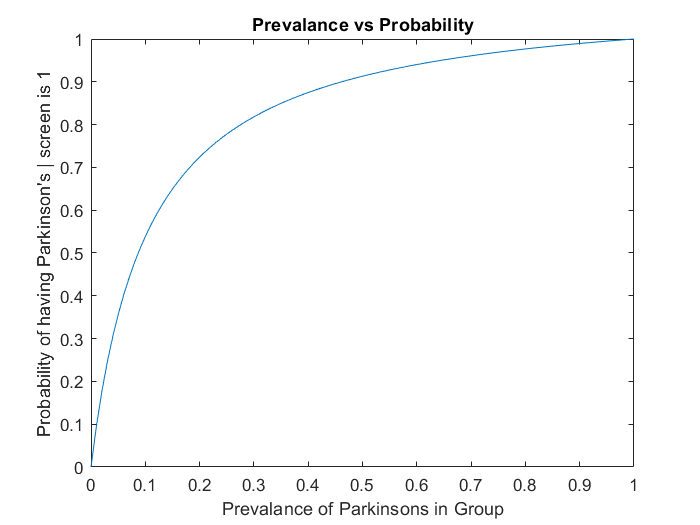

clear pr Psa Psplus
points = linspace(0,1); 
probs = linspace(0,1);

for index = 1:100
   pr = points(index);
   
   Psa = sum((data.actual == 1) & (data.screen == 1))/ (length(data.actual));
   Psplus = (1-pr)*(sum((data.actual==0)&(data.screen==1))/length(data.actual)) + pr*(sum((data.actual==1)&(data.screen==1))/length(data.actual));
 
   probs(index) = (Psa*pr)/Psplus;
   
end

plot(points, probs); 
title("Prevalance vs Probability");
xlabel("Prevalance of Parkinsons in Group");
ylabel("Probability of having Parkinson's | screen is 1")

#### 6.

I think that only those who have symptoms should be given the screen in order to avoid worrying people and using too many resources.

## Part 2

#### 8.

Yes, it does change as I expect. The chances of getting 0 and 1 change according to the probability.

#### 9.

The plot looks like a normal distribution centered around 1/2 the number of trials. This makes sense because if you have an equal chance of getting heads and tails then on average heads will come up for half of all trials.

#### 10. 

The chance of getting 19 heads in 37 trials would be 12.9%.

#### 11. 

The probability of getting 19 or fewer heads with a fair coin is 0.62859 and with a biased coin is 0.18198

#### 12.

When you change the mean the center of the distribution shifts from one side vs the other, and the standard deviation changes how spread out the distribution is. 

#### 13.

The mean changes how soon the s shape starts to curve up and the standard deviation changes whether it looks more like an S or a Z.

#### 14. 

1-density = 0.942

#### 15.

0.92